# This file works with the 'kalman.mlx' file

Steps:

Run this file then run the kalman.mlx. You can change the accuracy of the GPS sensor using the gpsSensor object.

clear all;
close all;
clc;

HoustonLLA = [29.760799, -95.369507, 25];
AustinLLA = [30.271129, -97.7436995, 500];
GPSdata = [];
trueNEDdata = [];

fs = 1;
duration = 60*30; % 30 minutes

bearing = 285; % degrees
distance = 235e3; % meters
distanceEast = distance*sind(bearing);
distanceNorth = distance*cosd(bearing);

HoustonNED = [0,0,0];
AustinNED = [distanceNorth,distanceEast,475];

trajectory = waypointTrajectory( ...
    'Waypoints', [HoustonNED;AustinNED], ...
    'TimeOfArrival',[0;duration], ...
    'SamplesPerFrame',5, ...
    'SampleRate',fs);

GPS = gpsSensor( ...
    'HorizontalPositionAccuracy',500, ...
    'VerticalPositionAccuracy',500, ...
    'SampleRate',fs, ...
    'DecayFactor', 0.1, ...
    'ReferenceLocation',HoustonLLA);

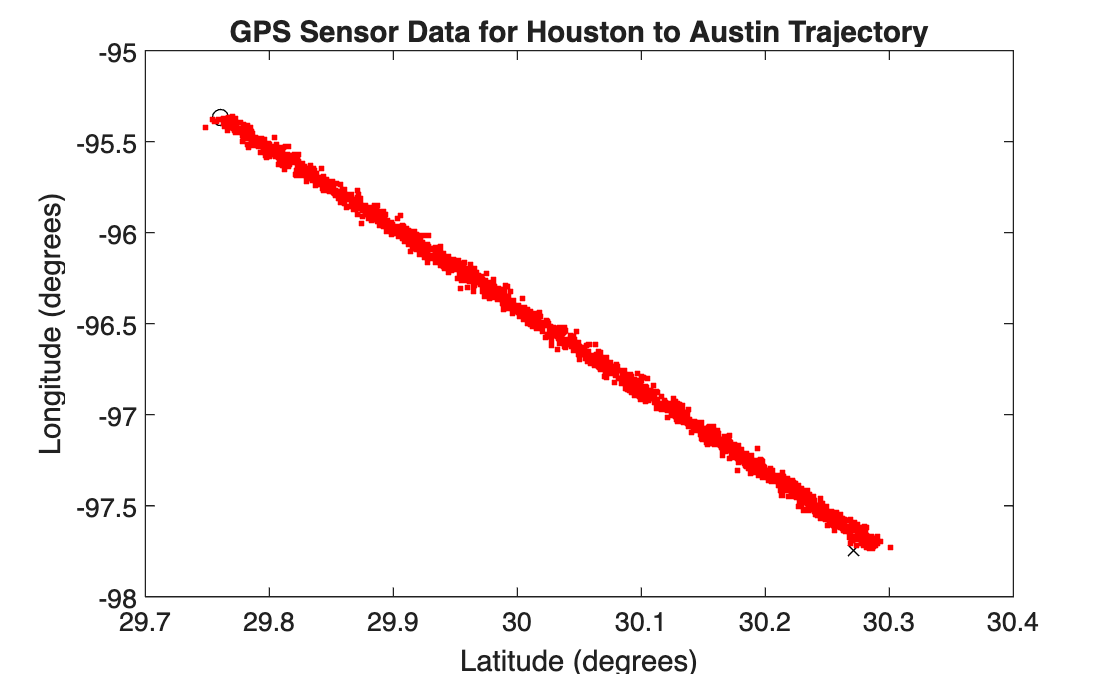

figure(1)
plot(HoustonLLA(1),HoustonLLA(2),'ko', ...
     AustinLLA(1),AustinLLA(2),'kx')
xlabel('Latitude (degrees)')
ylabel('Longitude (degrees)')
title('GPS Sensor Data for Houston to Austin Trajectory')
hold on

while ~isDone(trajectory)
    [truePositionNED,~,trueVelocityNED] = trajectory();
    reportedPositionLLA = GPS(truePositionNED,trueVelocityNED);

    figure(1)
    plot(reportedPositionLLA(:,1),reportedPositionLLA(:,2),'r.')
    GPSdata = [GPSdata; reportedPositionLLA];  % Store GPS positions
    trueNEDdata = [trueNEDdata; [truePositionNED, trueVelocityNED]];  % Store NED positions
end

save GPSdata GPSdata
save trueNEDdata trueNEDdata